## Set Up Workspace

clc; clear; close all;
addpath(genpath(pwd));
ieInit;

## **Read provided spectral radiance data of Pixel 4**

Load the spectral data of the spectral radiance measurements from each patch under the three illuminants

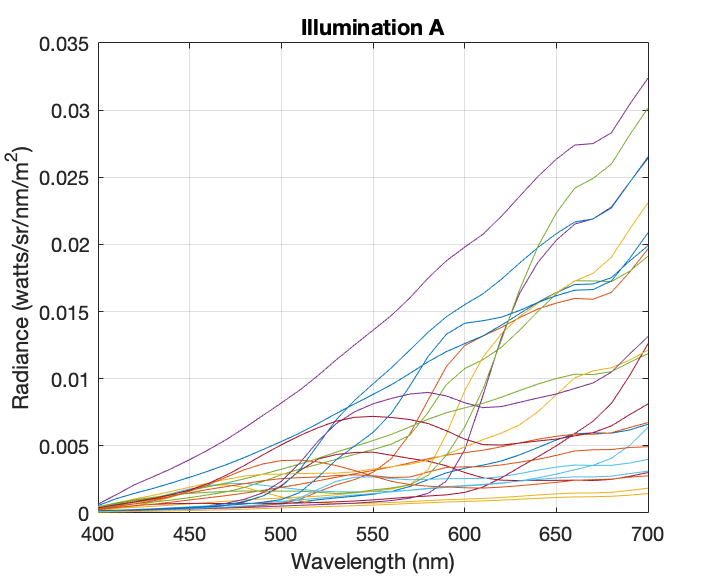

radiance_dir = '/your_path/mccSpectralRadianceAndLights1';
radiance_file = fullfile(radiance_dir, '20201023-mccRadianceData.mat');
wavelength = 400:10:700;
[radiance,wave] = ieReadSpectra(radiance_file,wavelength);
radiance_A = radiance(:,1:24);
radiance_CWF = radiance(:,25:48);
radiance_Day = radiance(:,49:72);
plotRadiance(wave,radiance_A);
title("Illumination A");

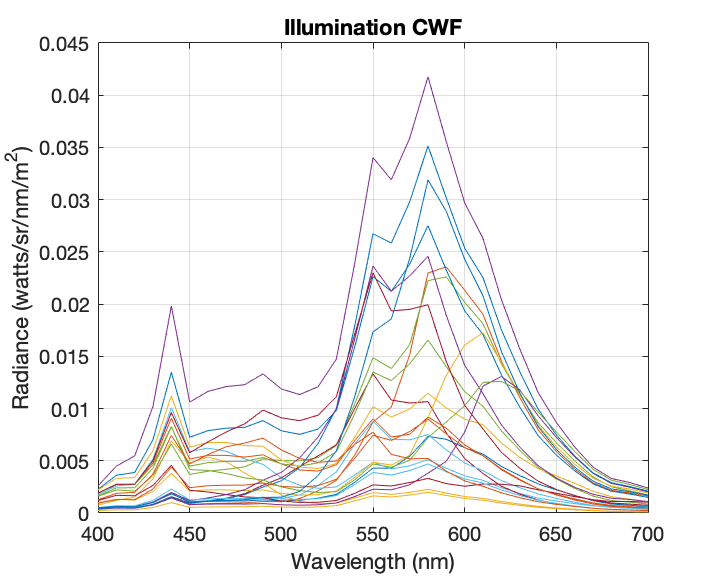

plotRadiance(wave,radiance_CWF);
title("Illumination CWF");

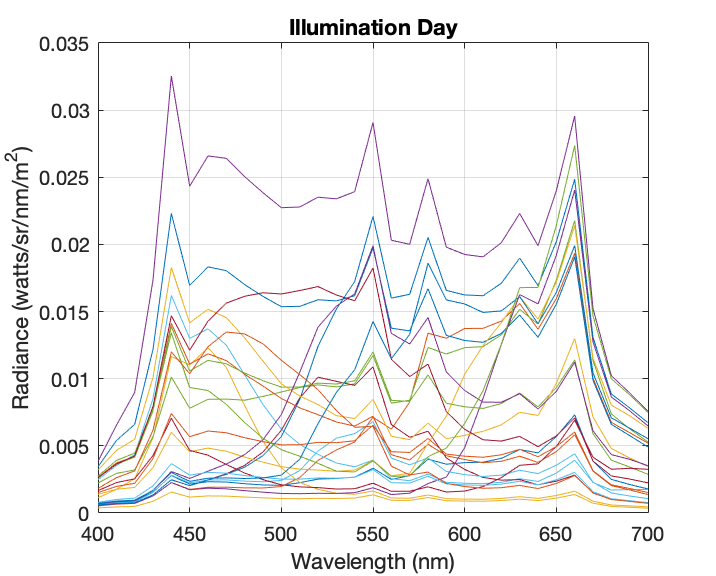

plotRadiance(wave, radiance_Day);
title("Illumination Day");

## **Create ISETCam Sensor, Get RGB - Illuminant A**

sensorA_file = fullfile('/your_path/DNG-mcc-measurement1/DNG-Illuminant-A','IMG_20201024_123128.dng');
thisRect = [1860  2010  350  255];
[sensorA, infoA] = sensorDNGRead(sensorA_file,'crop',thisRect);
sensorWindow(sensorA);
% cornerCWF = chartCornerpoints(sensorCWF)
cornerA = [38, 226; 317, 227; 317, 41; 39, 39];
blackBorder = true;
[rects, mLocs, pSize] = chartRectangles(cornerA, 4, 6, 0.5, blackBorder);

Black border


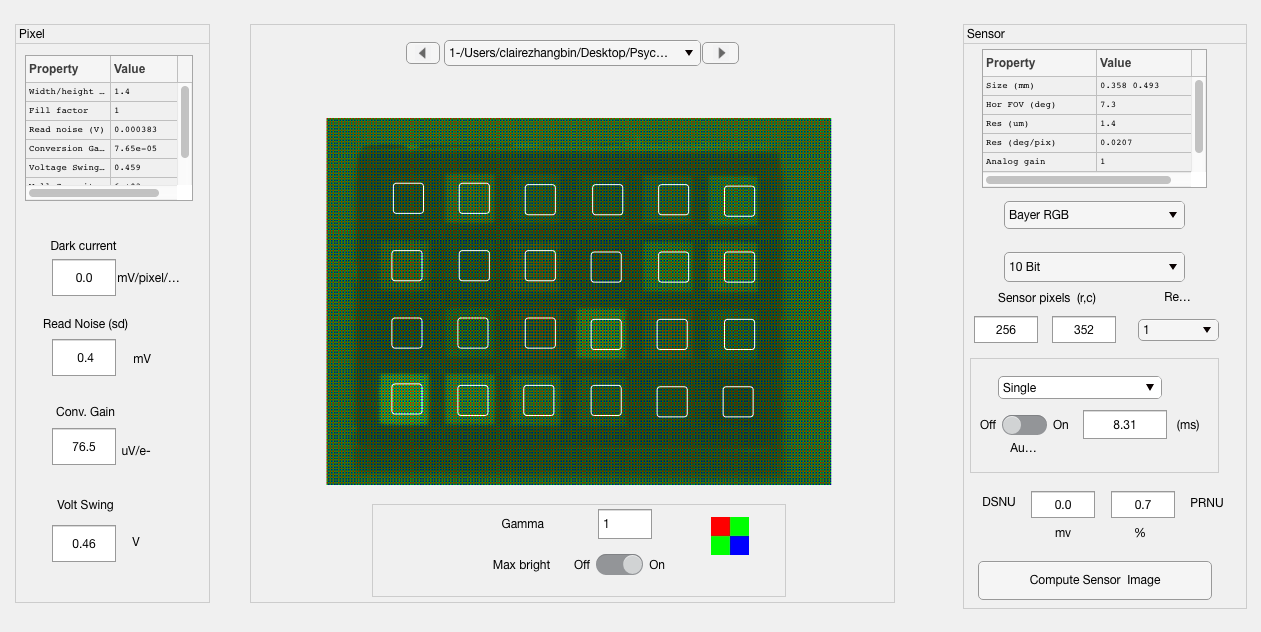

chartRectsDraw(sensorA, rects);

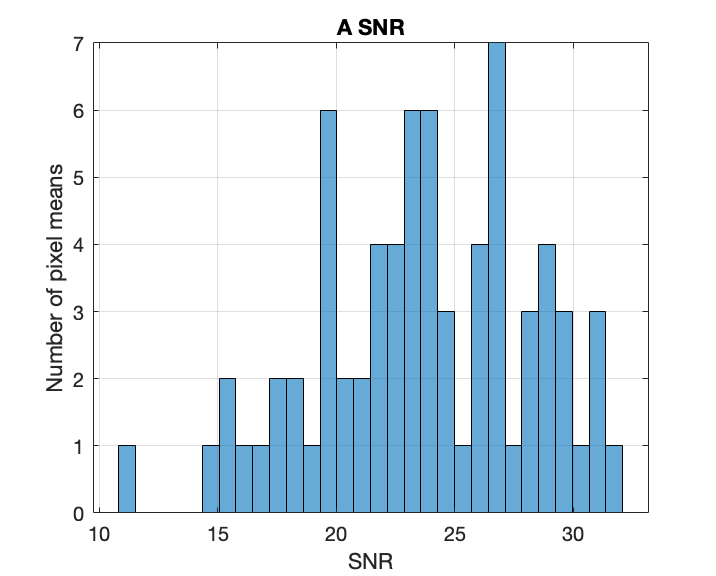

% correct RGB for black level and exposure time
nPixels = round(pSize(1)/4);
fullData = true;
dvalues = chartRectsData(sensorA, mLocs, nPixels, fullData , 'dv');
rgb_mean_A = zeros(24,3);
rgb_std_A = zeros(24,3);
for i = 1:24
    values = (dvalues{i} - infoA.BlackLevel(1)) ./ infoA.ExposureTime;
    rgb_mean_A(i,:) = nanmean(values);
    rgb_std_A(i,:) = nanstd(values);
end
% SNR check: mean RGB / std RGB
ieNewGraphWin;
histogram(log10(rgb_mean_A(:)./rgb_std_A(:))*20,30);
title("A SNR");
xlabel("SNR");ylabel("Number of pixel means");
grid on;

## **Create ISETCam Sensor, Get RGB - Illuminant CWF**

sensorCWF_file = fullfile('/your_path/DNG-mcc-measurement1/DNG-Illuminant-CWF','IMG_20201024_122900.dng');
thisRect = [1860  2010  350  255];
[sensorCWF, infoCWF] = sensorDNGRead(sensorCWF_file,'crop',thisRect);
sensorWindow(sensorCWF);
% cornerCWF = chartCornerpoints(sensorCWF)
cornerCWF = [63, 222; 339, 225; 339, 38; 63, 36];
blackBorder = true;
[rects, mLocs, pSize] = chartRectangles(cornerCWF, 4, 6, 0.5, blackBorder);

Black border


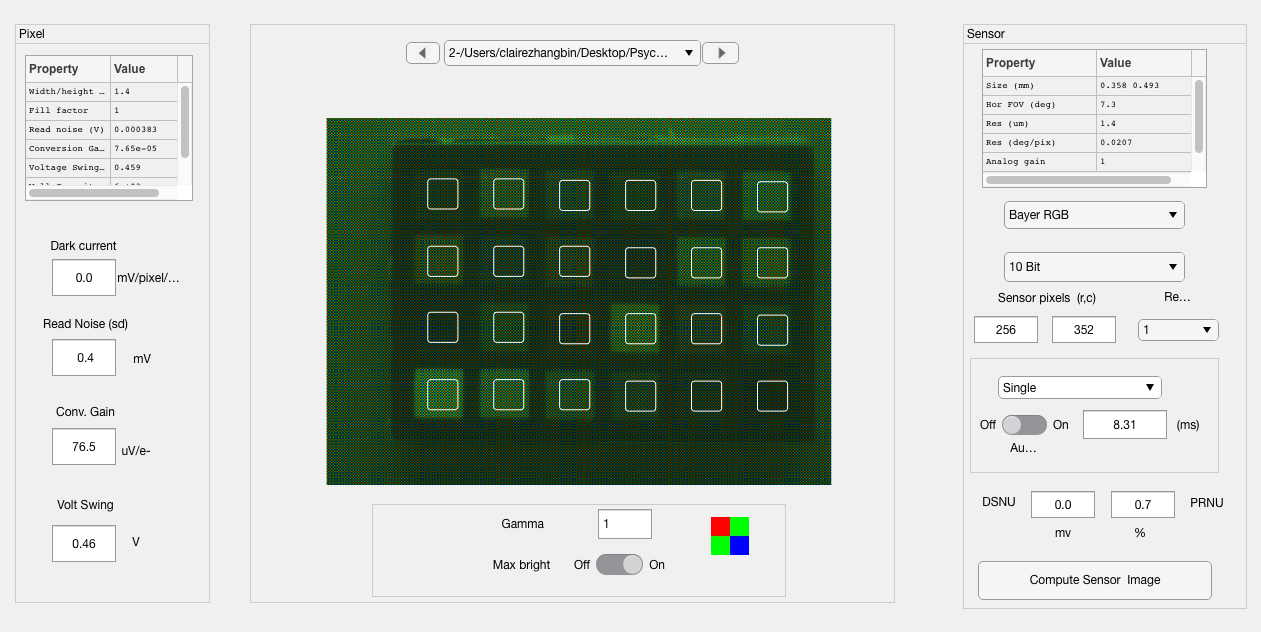

chartRectsDraw(sensorCWF, rects);

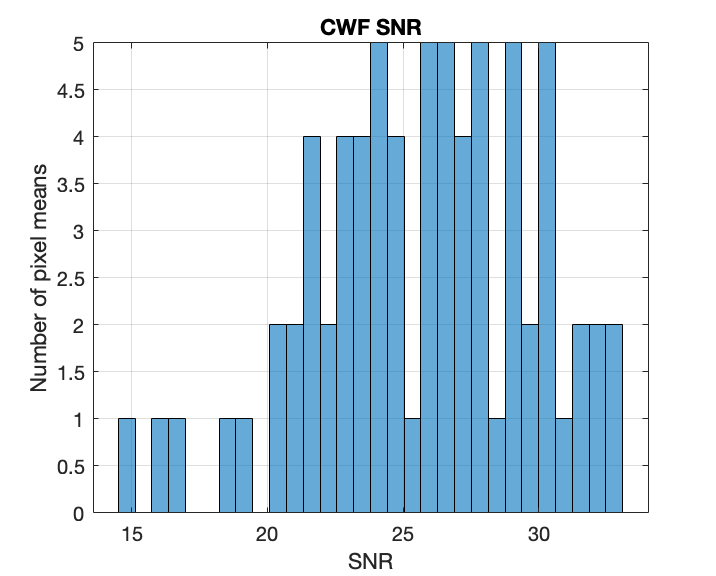

% correct RGB for black level and exposure time
nPixels = round(pSize(1)/4);
fullData = true;
dvalues = chartRectsData(sensorCWF, mLocs, nPixels, fullData , 'dv');
rgb_mean_CWF = zeros(24,3);
rgb_std_CWF = zeros(24,3);
for i = 1:24
    values = (dvalues{i} - infoCWF.BlackLevel(1)) ./ infoCWF.ExposureTime;
    rgb_mean_CWF(i,:) = nanmean(values);
    rgb_std_CWF(i,:) = nanstd(values);
end
% SNR check: mean RGB / std RGB
ieNewGraphWin;
histogram(log10(rgb_mean_CWF(:)./rgb_std_CWF(:))*20,30);
title("CWF SNR");
xlabel("SNR");ylabel("Number of pixel means");
grid on;

## **Create ISETCam Sensor, Get RGB - Illuminant Day**

sensorDay_file = fullfile('/your_path/DNG-mcc-measurement1/DNG-Illuminant-Day','IMG_20201024_122631.dng');
thisRect = [1860  2010  350  255];
[sensorDay, infoDay] = sensorDNGRead(sensorDay_file,'crop',thisRect);
sensorWindow(sensorDay);
% cornerDay = chartCornerpoints(sensorDay)
cornerDay = [72, 220; 345, 222; 347, 38; 72, 36];
blackBorder = true;
[rects, mLocs, pSize] = chartRectangles(cornerDay, 4, 6, 0.5, blackBorder);

Black border


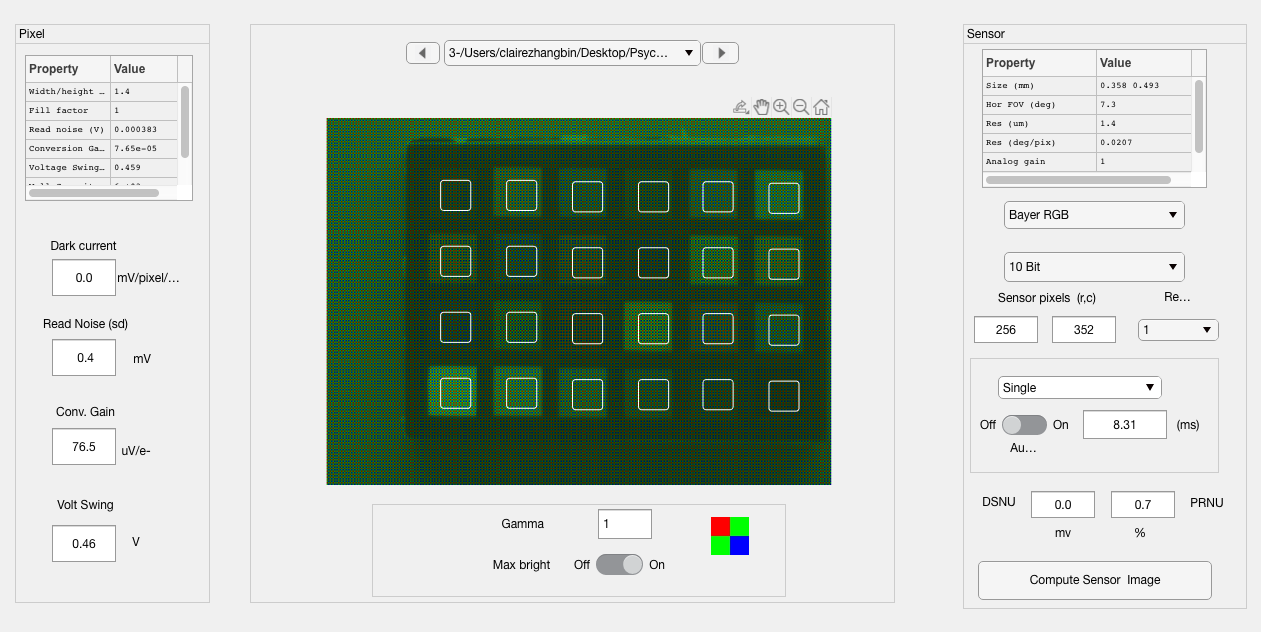

chartRectsDraw(sensorDay, rects);

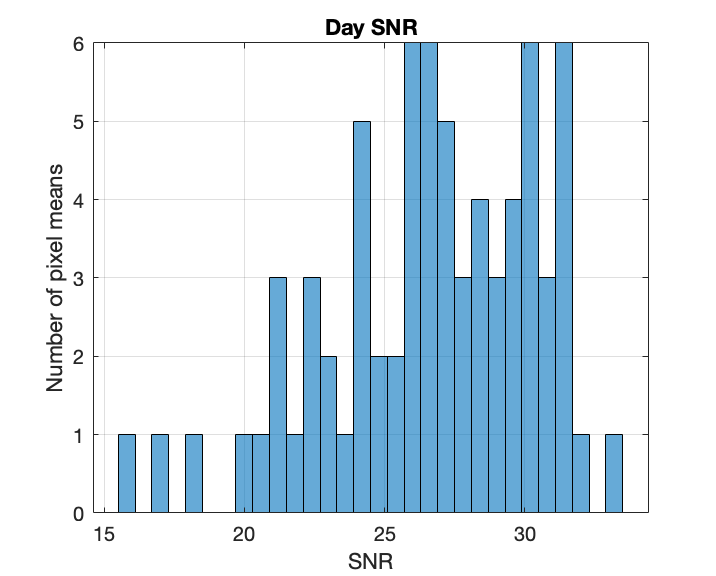

% correct RGB for black level and exposure time
nPixels = round(pSize(1)/4);
fullData = true;
dvalues = chartRectsData(sensorDay, mLocs, nPixels, fullData , 'dv');
rgb_mean_Day = zeros(24,3);
rgb_std_Day = zeros(24,3);
for i = 1:24
    values = (dvalues{i} - infoDay.BlackLevel(1)) ./ infoDay.ExposureTime;
    rgb_mean_Day(i,:) = nanmean(values);
    rgb_std_Day(i,:) = nanstd(values);
end
% SNR check: mean RGB / std RGB
ieNewGraphWin;
histogram(log10(rgb_mean_Day(:)./rgb_std_Day(:))*20,30);
title("Day SNR");
xlabel("SNR");ylabel("Number of pixel means");
grid on;

## Linear Equation

After loading and post-processing the input/output data from Google Pixel 4, we want to find the spectralQE that best approximates the two matrices. We can translate the problem into this following linear equation: 

                                                                                            RGB = Radiance' * SpectralQE,

where the dimensionality of the three matrices are RGB: 24 x 3, Radiance: 31 x 24, and SpectralQE: 31 x 3. Here 24 comes from the 24 color patches of MCC. 31 is the dimension of radiance data provided.

## **Strategy 1a: Pseudoinverse (Fitting the curve with radiance A only)**

The most convenient way to solve for a linear equation on matlab is to take a pseudoinverse. In the first attempt, we are going to use to radiance A to solve for spectral QE and see how well it works on the other two types of lights (cwf and day).

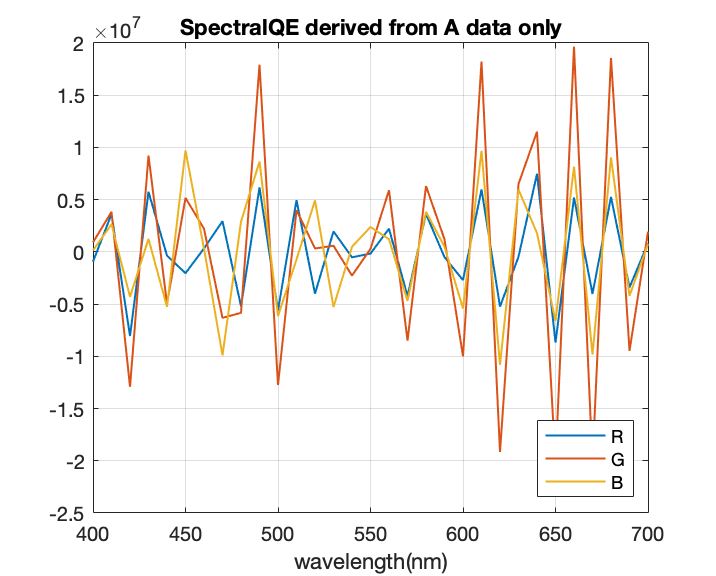

spectralQE_1a = pinv(radiance_A') * rgb_mean_A;
ieNewGraphWin;
plot(wavelength, spectralQE_1a,'LineWidth',1)
legend('R', 'G', 'B','location','southeast')
title("SpectralQE derived from A data only")
xlabel("wavelength(nm)")
grid on;

### If we use this spectralQE derived from A data, will it work on CWF or Day data?

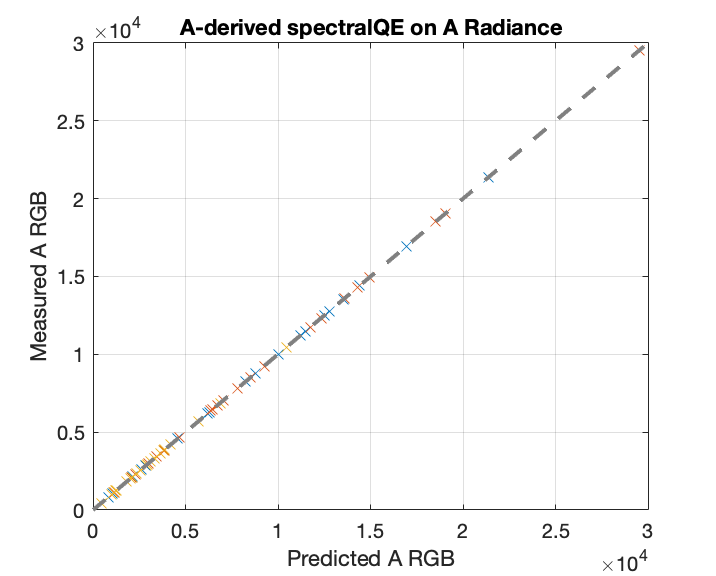

pred_A_1a = radiance_A' * spectralQE_1a;
ieNewGraphWin;
plot(pred_A_1a, rgb_mean_A,'x');
identityLine;
xlabel('Predicted A RGB')
ylabel('Measured A RGB')
title('A-derived spectralQE on A Radiance')

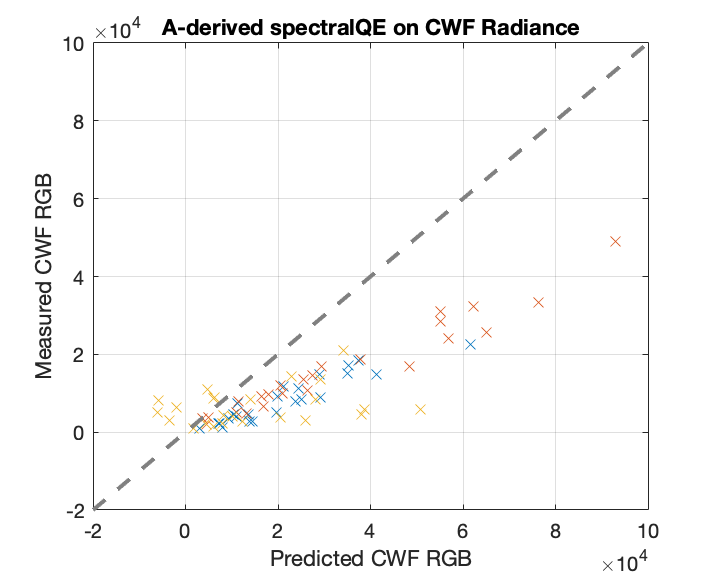

pred_CWF_1a = radiance_CWF' * spectralQE_1a;
ieNewGraphWin;
plot(pred_CWF_1a, rgb_mean_CWF,'x');
identityLine;
xlabel('Predicted CWF RGB')
ylabel('Measured CWF RGB')
title('A-derived spectralQE on CWF Radiance')

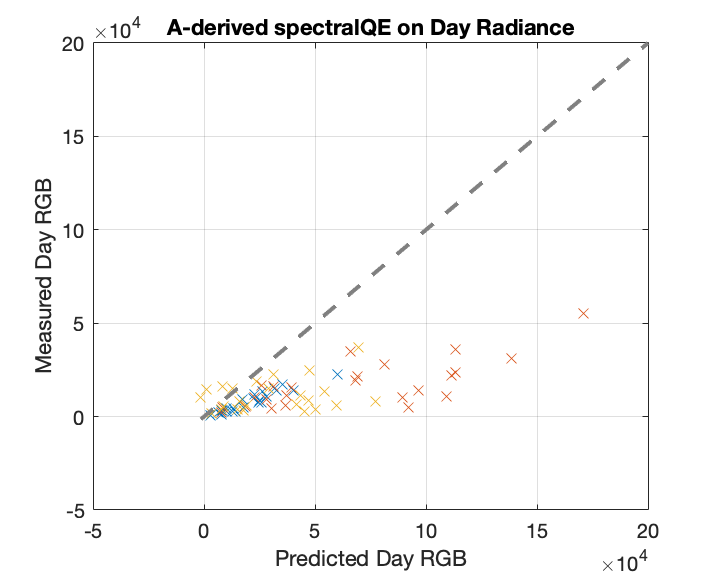

pred_Day_1a = radiance_Day' * spectralQE_1a;
ieNewGraphWin;
plot(pred_Day_1a, rgb_mean_Day,'x');
identityLine;
xlabel('Predicted Day RGB')
ylabel('Measured Day RGB')
title('A-derived spectralQE on Day Radiance')

We can see from here that the spectralQE derived from A overfits on A and does not generalize well on CWF and Day data.

## **Strategy 1b: Pseudoinverse (Fitting the curve with radiance A, CWF, and Day)**

Next, let's try finding a solution with all three types of radiance. We will do it by stacking the data for A, CWF, and Day to construct a bigger matrix. We randomly split the RGB and radiance data to two sets - 70% data for fitting set and 30% for held out test set, for cross validation.

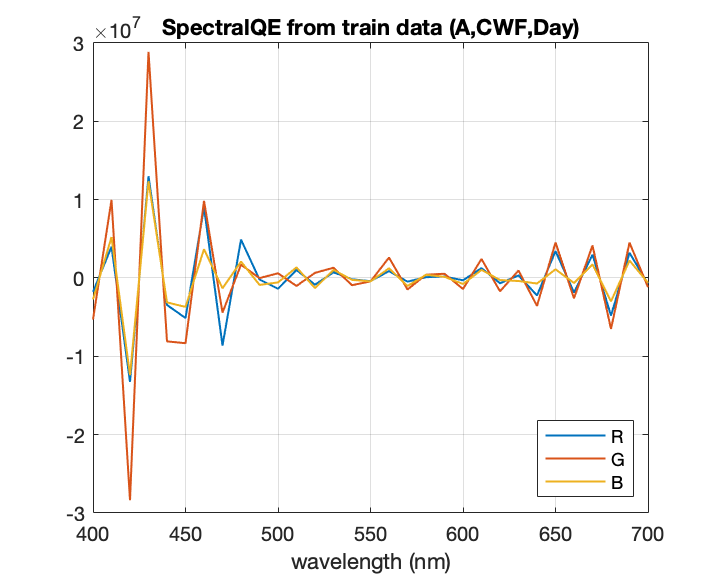

% complete RGB data
R_mean_all = [rgb_mean_A(:,1); rgb_mean_CWF(:,1); rgb_mean_Day(:,1)];
G_mean_all = [rgb_mean_A(:,2); rgb_mean_CWF(:,2); rgb_mean_Day(:,2)];
B_mean_all = [rgb_mean_A(:,3); rgb_mean_CWF(:,3); rgb_mean_Day(:,3)];

% index for train & validation splitting
m = size(R_mean_all,1);
rng('default');
idx = randperm(m);
p = 0.7;

% train RGB & test RGB
train_R_mean = R_mean_all(idx(1:round(p*m)));
test_R_mean = R_mean_all(idx(round(p*m)+1:end));
train_G_mean = G_mean_all(idx(1:round(p*m)));
test_G_mean = G_mean_all(idx(round(p*m)+1:end));
train_B_mean = B_mean_all(idx(1:round(p*m)));
test_B_mean = B_mean_all(idx(round(p*m)+1:end));
test_RGB_mean = [test_R_mean, test_G_mean, test_B_mean];
train_RGB_mean = [train_R_mean, train_G_mean, train_B_mean];

% train radiance & test radiance
radiance_all = [radiance_A'; radiance_CWF'; radiance_Day'];
train_radiance = radiance_all(idx(1:round(p*m)),:);
test_radiance = radiance_all(idx(round(p*m)+1:end),:);

% fit spectralQE
QE_R = pinv(train_radiance' * train_radiance)*train_radiance'*train_R_mean;
QE_G = pinv(train_radiance' * train_radiance)*train_radiance'*train_G_mean;
QE_B = pinv(train_radiance' * train_radiance)*train_radiance'*train_B_mean;
spectralQE_1b = [QE_R, QE_G, QE_B];
ieNewGraphWin;
plot(wavelength, spectralQE_1b,'linewidth',1)
legend('R', 'G', 'B','location','southeast')
title("SpectralQE from train data (A,CWF,Day)")
xlabel("wavelength (nm)")
grid on;

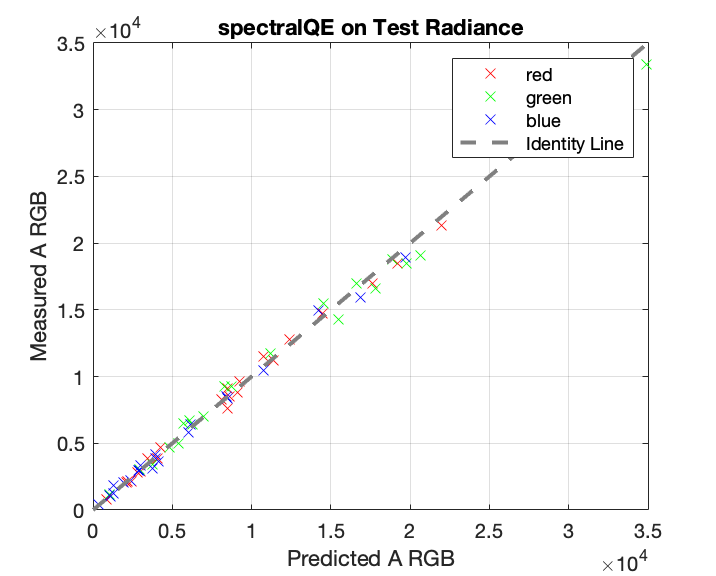

% how well does it fit on the test data
pred_test_1b = test_radiance*spectralQE_1b;
ieNewGraphWin;
plot(pred_test_1b(:,1),test_R_mean,'x','Color','red');
hold on
plot(pred_test_1b(:,2),test_G_mean,'x','Color','green');
plot(pred_test_1b(:,3),test_B_mean,'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted A RGB')
ylabel('Measured A RGB')
title('spectralQE on Test Radiance')

pred_test_1b_converted = pred_test_1b .* infoA.ExposureTime + infoA.BlackLevel(1);
test_RGB_mean_converted = test_RGB_mean .* infoA.ExposureTime + infoA.BlackLevel(1);
% disp(['mean square error: ', num2str(immse(pred_test_1b_converted,test_RGB_mean_converted))])

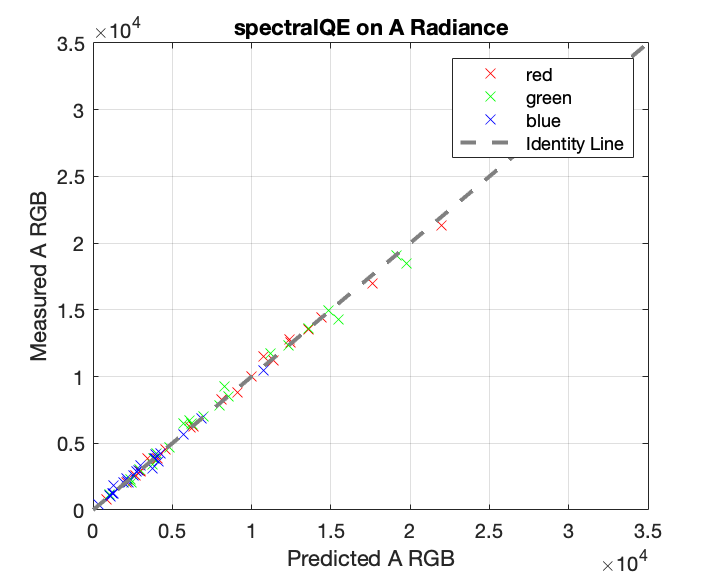

% how well does the spectralQE work on all A, CWF, Day data individually
pred_A_1b = radiance_A' * spectralQE_1b;
ieNewGraphWin;
plot(pred_A_1b(:,1),rgb_mean_A(:,1),'x','Color','red');
hold on
plot(pred_A_1b(:,2),rgb_mean_A(:,2),'x','Color','green');
plot(pred_A_1b(:,3),rgb_mean_A(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted A RGB')
ylabel('Measured A RGB')
title('spectralQE on A Radiance')

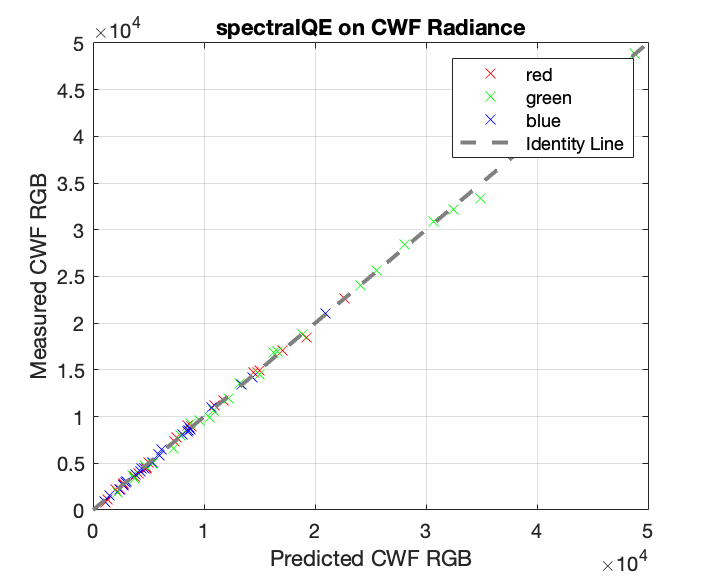

pred_CWF_1b = radiance_CWF' * spectralQE_1b;
ieNewGraphWin;
plot(pred_CWF_1b(:,1),rgb_mean_CWF(:,1),'x','Color','red');
hold on
plot(pred_CWF_1b(:,2),rgb_mean_CWF(:,2),'x','Color','green');
plot(pred_CWF_1b(:,3),rgb_mean_CWF(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted CWF RGB')
ylabel('Measured CWF RGB')
title('spectralQE on CWF Radiance')

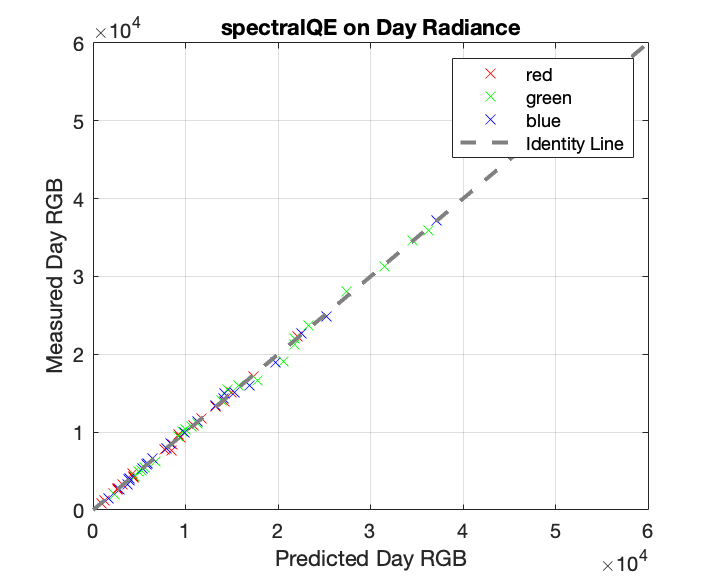

pred_Day_1b = radiance_Day' * spectralQE_1b;
ieNewGraphWin;
plot(pred_Day_1b(:,1),rgb_mean_Day(:,1),'x','Color','red');
hold on
plot(pred_Day_1b(:,2),rgb_mean_Day(:,2),'x','Color','green');
plot(pred_Day_1b(:,3),rgb_mean_Day(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted Day RGB')
ylabel('Measured Day RGB')
title('spectralQE on Day Radiance')

The spectral QE curves seem to be very off but the measured vs predicted RGB values appear to be perfect, which means the data have been overfitted. This is definitely not a good approach.

## **Strategy 2a - SVD (with radiance A)**

The overfitting in the previous two attempts are caused by the relateively high dimensionality of our model. Therefore, the better way to fix the issue is to first find out to what extent we should reduce the dimensionality to. We can do that by looking at the singular values given by SVD. In the following graph, we see that the singular values decreases significantly after the first 3 to 4 elements. This implies that the number of principle components is approximately 4, and that's what we should set the dimension to in order to avoid overfitting.

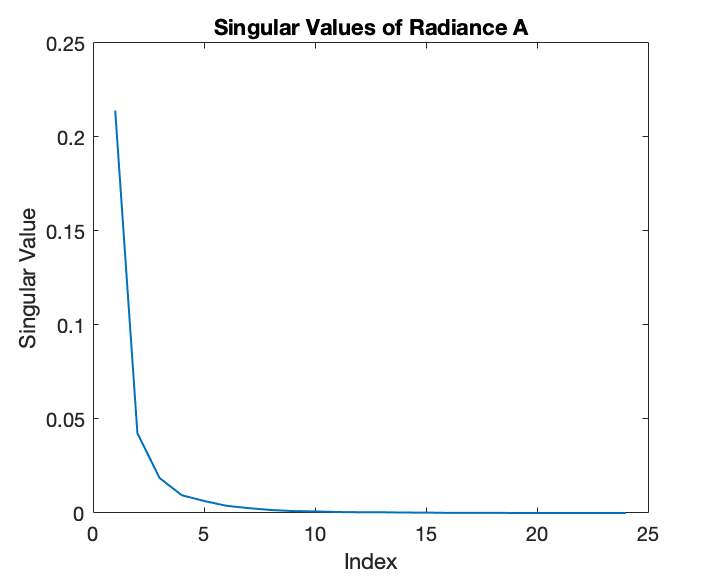

[U,S,V] = svd(radiance_A');
S_val = diag(S);
ieNewGraphWin;
plot(1:size(S_val), S_val,'linewidth',1)
title("Singular Values of Radiance A")
xlabel('Index')
ylabel('Singular Value')

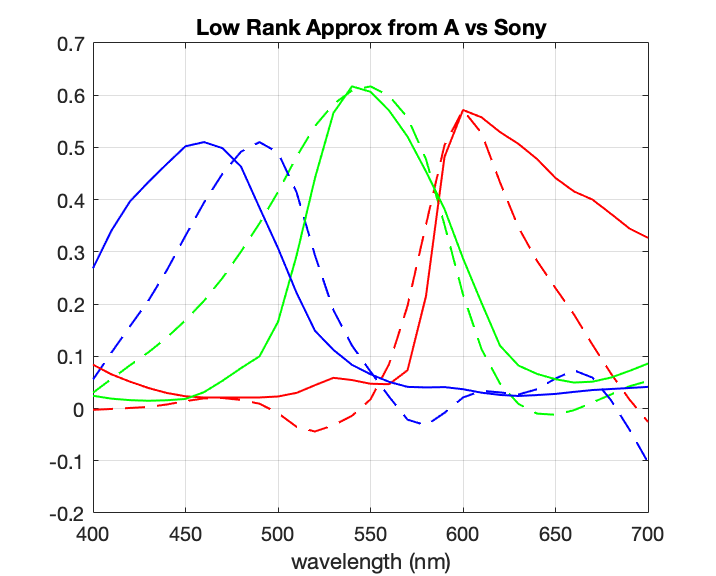

% reconstruct radiance_A
radiance_A_new = U(:,1:4) * S(1:4,1:4) * V(:,1:4)';
spectralQE_2a = pinv(radiance_A_new) * rgb_mean_A;
sonyQE = ieReadSpectra('qe_IMX363_public.mat', wavelength);
mx_r = max(sonyQE(:,1));
mx_g = max(sonyQE(:,2));
mx_b = max(sonyQE(:,3));
spectralQE_2a_r_scaled = ieScale(spectralQE_2a(:,1),mx_r);
spectralQE_2a_g_scaled = ieScale(spectralQE_2a(:,2),mx_g);
spectralQE_2a_b_scaled = ieScale(spectralQE_2a(:,3),mx_b);
ieNewGraphWin;
plot(wavelength, spectralQE_2a_r_scaled,'r--',...
     wavelength, spectralQE_2a_g_scaled,'g--',...
     wavelength, spectralQE_2a_b_scaled,'b--','linewidth',1);
grid on;
hold on;
plot(wavelength, sonyQE(:,1),'r',...
     wavelength, sonyQE(:,2),'g',...
     wavelength, sonyQE(:,3),'b','linewidth',1);
xlabel("wavelength (nm)")
title('Low Rank Approx from A vs Sony')

We can compare the spectral QE curves we obtained with the one from Sony. The curves are similar in shape. Also, by comparing the measured data with predicted data, we can see that this approach gives satisfactory results (relatively low bias and low variance).

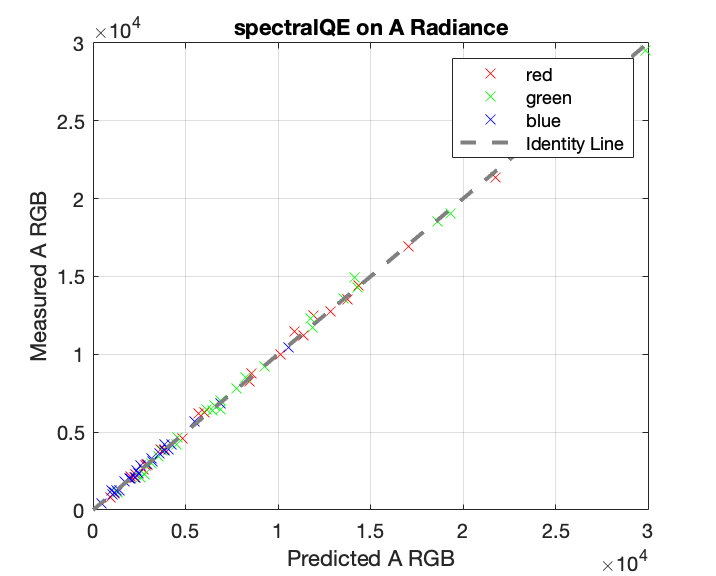

pred_A_2a = radiance_A' * spectralQE_2a;
ieNewGraphWin;
plot(pred_A_2a(:,1),rgb_mean_A(:,1),'x','Color','red');
hold on
plot(pred_A_2a(:,2),rgb_mean_A(:,2),'x','Color','green');
plot(pred_A_2a(:,3),rgb_mean_A(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted A RGB')
ylabel('Measured A RGB')
title('spectralQE on A Radiance')

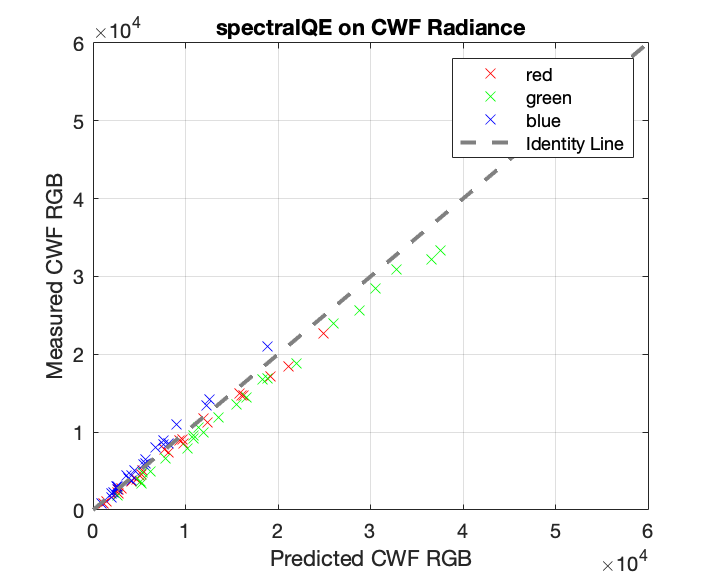

pred_CWF_2a = radiance_CWF' * spectralQE_2a;
ieNewGraphWin;
plot(pred_CWF_2a(:,1),rgb_mean_CWF(:,1),'x','Color','red');
hold on
plot(pred_CWF_2a(:,2),rgb_mean_CWF(:,2),'x','Color','green');
plot(pred_CWF_2a(:,3),rgb_mean_CWF(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted CWF RGB')
ylabel('Measured CWF RGB')
title('spectralQE on CWF Radiance')

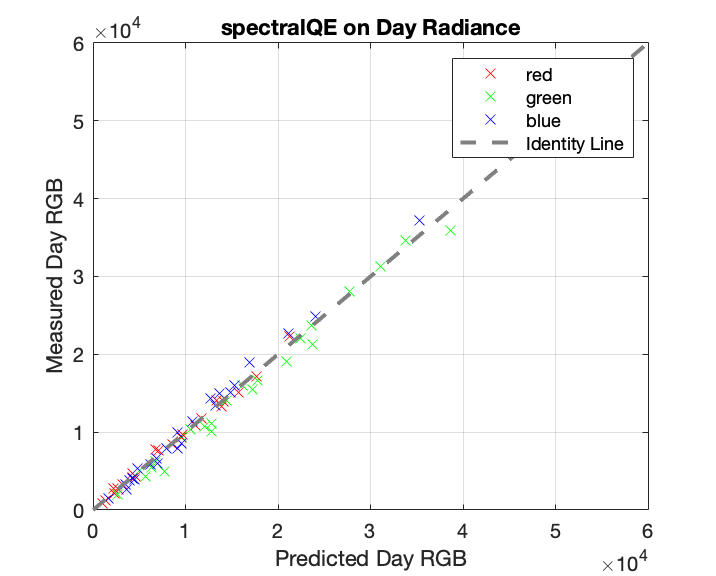

pred_Day_2a = radiance_Day' * spectralQE_2a;
ieNewGraphWin;
plot(pred_Day_2a(:,1),rgb_mean_Day(:,1),'x','Color','red');
hold on
plot(pred_Day_2a(:,2),rgb_mean_Day(:,2),'x','Color','green');
plot(pred_Day_2a(:,3),rgb_mean_Day(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted Day RGB')
ylabel('Measured Day RGB')
title('spectralQE on Day Radiance')

## **Strategy 2b: SVD with fitting set (A, CWF, Day), test on held out test set**

We create larger RGB and radiance matrices by stacking data from A, CWF, and Day. We then use the splitting mentioned previously to split the data into fitting set and validation set for cross validation.

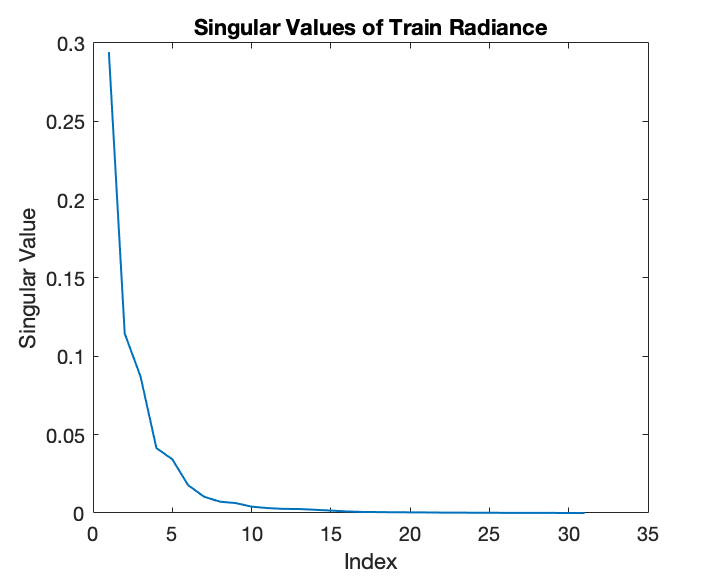

[U_all,S_all,V_all] = svd(train_radiance);
S_val_all = diag(S_all);
ieNewGraphWin;
plot(1:size(S_val_all), S_val_all,'linewidth',1)
title("Singular Values of Train Radiance")
xlabel('Index')
ylabel('Singular Value')

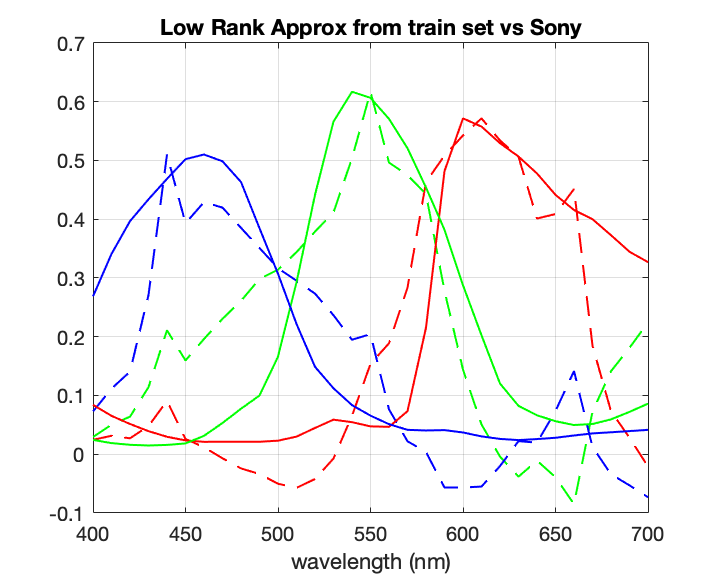

% reconstruct train_radiance
train_radiance_new = U_all(:,1:4) * S_all(1:4,1:4) * V_all(:,1:4)';
spectralQE_2b = pinv(train_radiance_new) * train_RGB_mean;
spectralQE_2b_r_scaled = ieScale(spectralQE_2b(:,1),mx_r);
spectralQE_2b_g_scaled = ieScale(spectralQE_2b(:,2),mx_g);
spectralQE_2b_b_scaled = ieScale(spectralQE_2b(:,3),mx_b);
ieNewGraphWin;
plot(wavelength, spectralQE_2b_r_scaled,'r--',...
     wavelength, spectralQE_2b_g_scaled,'g--',...
     wavelength, spectralQE_2b_b_scaled,'b--','linewidth',1);
grid on;
hold on;
plot(wavelength, sonyQE(:,1),'r',...
     wavelength, sonyQE(:,2),'g',...
     wavelength, sonyQE(:,3),'b','linewidth',1);
xlabel("wavelength (nm)")
title('Low Rank Approx from train set vs Sony')

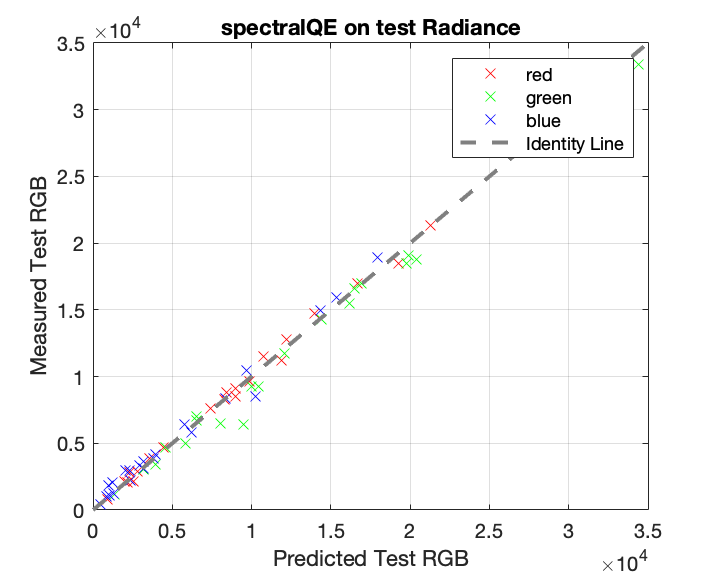

% how well does it fit on the test data
pred_test_2b = test_radiance*spectralQE_2b;
ieNewGraphWin;
plot(pred_test_2b(:,1),test_R_mean,'x','Color','red');
hold on
plot(pred_test_2b(:,2),test_G_mean,'x','Color','green');
plot(pred_test_2b(:,3),test_B_mean,'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted Test RGB')
ylabel('Measured Test RGB')
title('spectralQE on test Radiance')

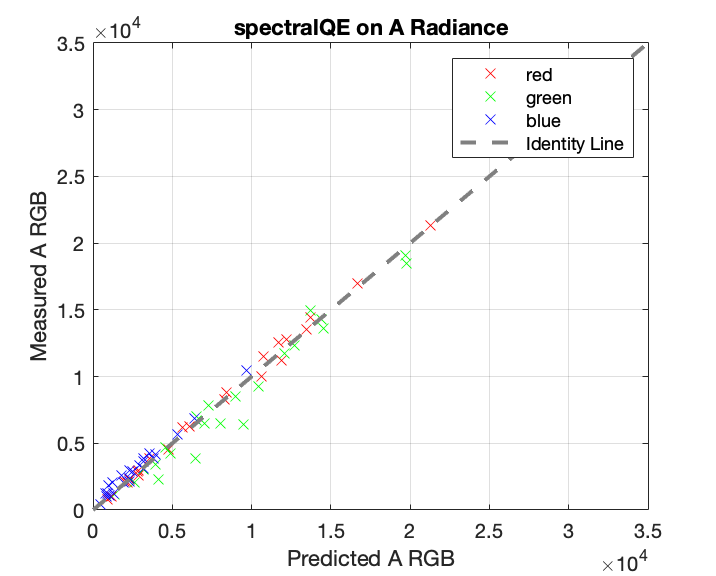

pred_test_2b_converted = pred_test_2b .* infoA.ExposureTime + infoA.BlackLevel(1);
% disp([' mean square error is ', num2str(immse(pred_test_2b_converted,test_RGB_mean_converted))])
pred_A_2b = radiance_A' * spectralQE_2b;
ieNewGraphWin;
plot(pred_A_2b(:,1),rgb_mean_A(:,1),'x','Color','red');
hold on
plot(pred_A_2b(:,2),rgb_mean_A(:,2),'x','Color','green');
plot(pred_A_2b(:,3),rgb_mean_A(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted A RGB')
ylabel('Measured A RGB')
title('spectralQE on A Radiance')

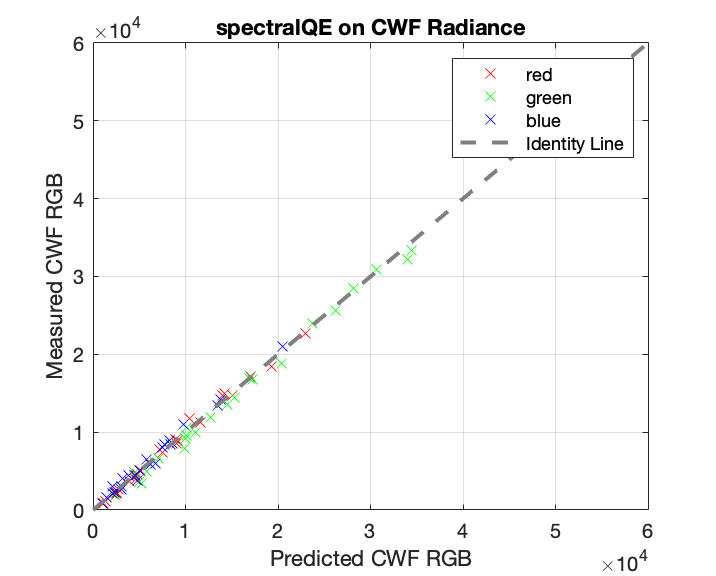

pred_CWF_2b = radiance_CWF' * spectralQE_2b;
ieNewGraphWin;
plot(pred_CWF_2b(:,1),rgb_mean_CWF(:,1),'x','Color','red');
hold on
plot(pred_CWF_2b(:,2),rgb_mean_CWF(:,2),'x','Color','green');
plot(pred_CWF_2b(:,3),rgb_mean_CWF(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted CWF RGB')
ylabel('Measured CWF RGB')
title('spectralQE on CWF Radiance')

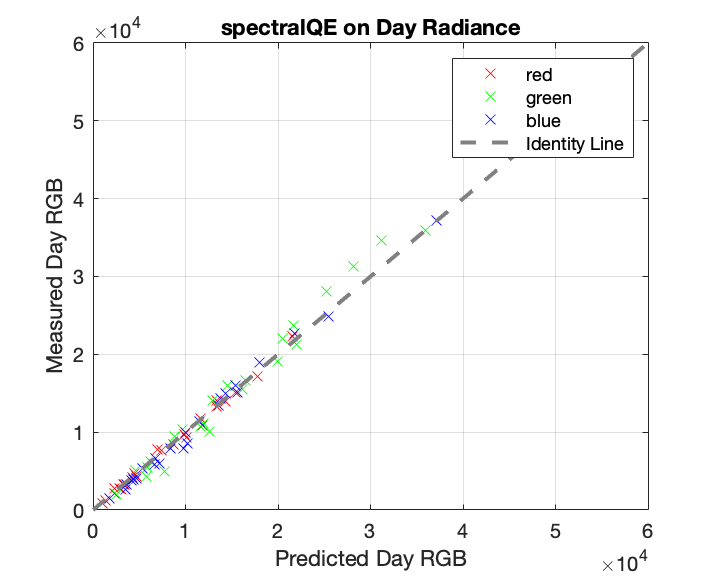

pred_Day_2b = radiance_Day' * spectralQE_2b;
ieNewGraphWin;
plot(pred_Day_2b(:,1),rgb_mean_Day(:,1),'x','Color','red');
hold on
plot(pred_Day_2b(:,2),rgb_mean_Day(:,2),'x','Color','green');
plot(pred_Day_2b(:,3),rgb_mean_Day(:,3),'x','Color','blue');
identityLine;
legend('red','green','blue','Identity Line')
xlabel('Predicted Day RGB')
ylabel('Measured Day RGB')
title('spectralQE on Day Radiance')

## **Model Assessments III - CIELAB**

Next, we want to know how good our models are by comparing predicted and mesaured outputs with the CIELAB color metrics. We do so by generating the predicted output images with given inputs and the fitted model and then calculating the color difference (in CIELAB metrics) between predicted and actual pixel values of each of the 24 patches.

cielab_diff_1b = calculate_cielab_diff(pred_test_1b_converted, test_RGB_mean_converted);
disp(['The average CIELAB deltaE on test data for method 1b (train data, no SVD) is ', num2str(mean(cielab_diff_1b))]);

The average CIELAB deltaE on test data for method 1b (train data, no SVD) is 2.2979


cielab_diff_2b = calculate_cielab_diff(pred_test_2b_converted, test_RGB_mean_converted);
disp(['The average CIELAB deltaE on test data for method 2b (train data, with SVD) is ', num2str(mean(cielab_diff_2b))]);

The average CIELAB deltaE on test data for method 2b (train data, with SVD) is 4.6271


## **Visualization**

% 24 patches 4x6
for ii=1:24
    row = mod(ii,4);
    col = floor(ii/4)+1;
    if row == 0
        row = 4;
        col = col - 1;
    end
    
    % === lighting A === %
    meas_A_rgb = rgb_mean_A .* infoA.ExposureTime + infoA.BlackLevel(1);
    meas_A_denom = max(max(meas_A_rgb));
    meas_A_img = ones(80).*permute(meas_A_rgb(ii,:)./meas_A_denom,[1 3 2]);
    meas_A_mat((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = meas_A_img;
    
    pred_A_rgb1 = pred_A_1b .* infoA.ExposureTime + infoA.BlackLevel(1);
    pred_A_denom1 = max(max(pred_A_rgb1));
    pred_A_img1 = ones(80).*permute(pred_A_rgb1(ii,:)./pred_A_denom1,[1 3 2]);
    pred_A_mat1((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = pred_A_img1;
    
    pred_A_rgb2 = pred_A_2b .* infoA.ExposureTime + infoA.BlackLevel(1);
    pred_A_denom2 = max(max(pred_A_rgb2));
    pred_A_img2 = ones(80).*permute(pred_A_rgb2(ii,:)./pred_A_denom2,[1 3 2]);
    pred_A_mat2((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = pred_A_img2;
    
    % === lighting CWF === %
    meas_CWF_rgb = rgb_mean_CWF .* infoCWF.ExposureTime + infoCWF.BlackLevel(1);
    meas_CWF_denom = max(max(meas_CWF_rgb));
    meas_CWF_img = ones(80).*permute(meas_CWF_rgb(ii,:)./meas_CWF_denom,[1 3 2]);
    meas_CWF_mat((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = meas_CWF_img;
    
    pred_CWF_rgb1 = pred_CWF_1b .* infoCWF.ExposureTime + infoCWF.BlackLevel(1);
    pred_CWF_denom1 = max(max(pred_CWF_rgb1));
    pred_CWF_img1 = ones(80).*permute(pred_CWF_rgb1(ii,:)./pred_CWF_denom1,[1 3 2]);
    pred_CWF_mat1((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = pred_CWF_img1;
    
    pred_CWF_rgb2 = pred_CWF_2b .* infoCWF.ExposureTime + infoCWF.BlackLevel(1);
    pred_CWF_denom2 = max(max(pred_CWF_rgb2));
    pred_CWF_img2 = ones(80).*permute(pred_CWF_rgb2(ii,:)./pred_CWF_denom2,[1 3 2]);
    pred_CWF_mat2((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = pred_CWF_img2;
    
    % === lighting Day === %
    meas_Day_rgb = rgb_mean_Day .* infoDay.ExposureTime + infoDay.BlackLevel(1);
    meas_Day_denom = max(max(meas_Day_rgb));
    meas_Day_img = ones(80).*permute(meas_Day_rgb(ii,:)./meas_Day_denom,[1 3 2]);
    meas_Day_mat((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = meas_Day_img;
    
    pred_Day_rgb1 = pred_Day_1b .* infoDay.ExposureTime + infoDay.BlackLevel(1);
    pred_Day_denom1 = max(max(pred_Day_rgb1));
    pred_Day_img1 = ones(80).*permute(pred_Day_rgb1(ii,:)./pred_Day_denom1,[1 3 2]);
    pred_Day_mat1((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = pred_Day_img1;
    
    pred_Day_rgb2 = pred_Day_2b .* infoDay.ExposureTime + infoDay.BlackLevel(1);
    pred_Day_denom2 = max(max(pred_Day_rgb2));
    pred_Day_img2 = ones(80).*permute(pred_Day_rgb2(ii,:)./pred_Day_denom2,[1 3 2]);
    pred_Day_mat2((row-1)*80+1:row*80, (col-1)*80+1:col*80,:) = pred_Day_img2;
    
end



pred_A_2b_converted = pred_A_2b .* infoA.ExposureTime + infoA.BlackLevel(1);
pred_A_1b_converted = pred_A_1b .* infoA.ExposureTime + infoA.BlackLevel(1);
A_RGB_mean_converted = rgb_mean_A .* infoA.ExposureTime + infoA.BlackLevel(1);
cielab_diff_A_1b = calculate_cielab_diff(pred_A_1b_converted, A_RGB_mean_converted);
cielab_diff_A_2b = calculate_cielab_diff(pred_A_2b_converted, A_RGB_mean_converted);
disp(['cielab_diff_A_1b: ', num2str(mean(cielab_diff_A_1b))]);

cielab_diff_A_1b: 1.5384


disp(['cielab_diff_A_2b: ', num2str(mean(cielab_diff_A_2b))]);

cielab_diff_A_2b: 5.043



pred_CWF_2b_converted = pred_CWF_2b .* infoCWF.ExposureTime + infoCWF.BlackLevel(1);
pred_CWF_1b_converted = pred_CWF_1b .* infoCWF.ExposureTime + infoCWF.BlackLevel(1);
CWF_RGB_mean_converted = rgb_mean_CWF .* infoCWF.ExposureTime + infoCWF.BlackLevel(1);
cielab_diff_CWF_1b = calculate_cielab_diff(pred_CWF_1b_converted, CWF_RGB_mean_converted);
cielab_diff_CWF_2b = calculate_cielab_diff(pred_CWF_2b_converted, CWF_RGB_mean_converted);
disp(['cielab_diff_CWF_1b: ', num2str(mean(cielab_diff_CWF_1b))]);

cielab_diff_CWF_1b: 0.82624


disp(['cielab_diff_CWF_2b: ', num2str(mean(cielab_diff_CWF_2b))]);

cielab_diff_CWF_2b: 3.1201



pred_Day_2b_converted = pred_Day_2b .* infoDay.ExposureTime + infoDay.BlackLevel(1);
pred_Day_1b_converted = pred_Day_1b .* infoDay.ExposureTime + infoDay.BlackLevel(1);
Day_RGB_mean_converted = rgb_mean_Day .* infoDay.ExposureTime + infoDay.BlackLevel(1);
cielab_diff_Day_1b = calculate_cielab_diff(pred_Day_1b_converted, Day_RGB_mean_converted);
cielab_diff_Day_2b = calculate_cielab_diff(pred_Day_2b_converted, Day_RGB_mean_converted);
disp(['cielab_diff_Day_1b: ', num2str(mean(cielab_diff_Day_1b))]);

cielab_diff_Day_1b: 0.76533


disp(['cielab_diff_Day_2b: ', num2str(mean(cielab_diff_Day_2b))]);

cielab_diff_Day_2b: 4.6688


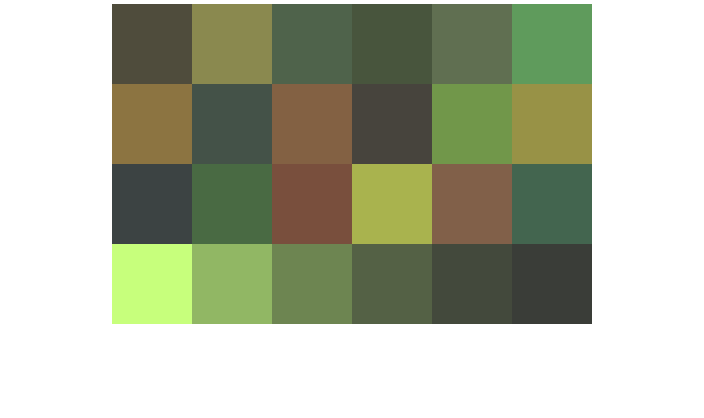

ieNewGraphWin;
imshow(meas_A_mat)
title("A Ground Truth")

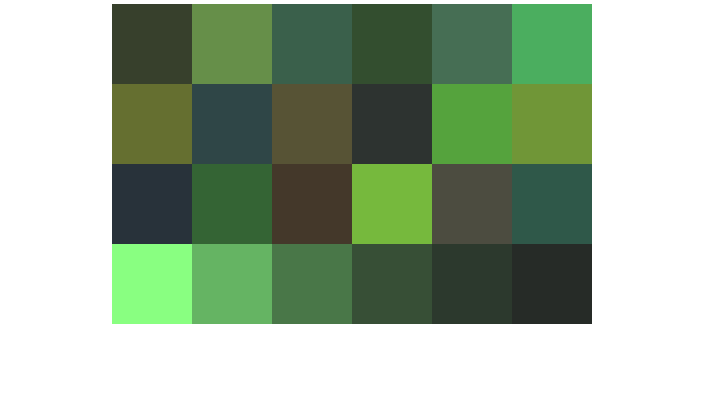

ieNewGraphWin;
imshow(meas_CWF_mat)
title("CWF Ground Truth")

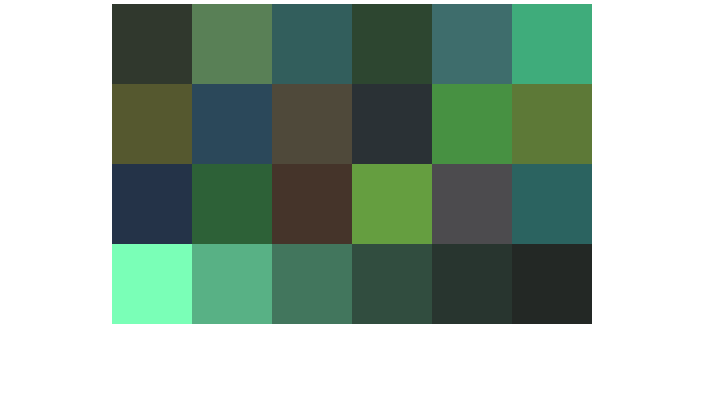

ieNewGraphWin;
imshow(meas_Day_mat)
title("Day Ground Truth")

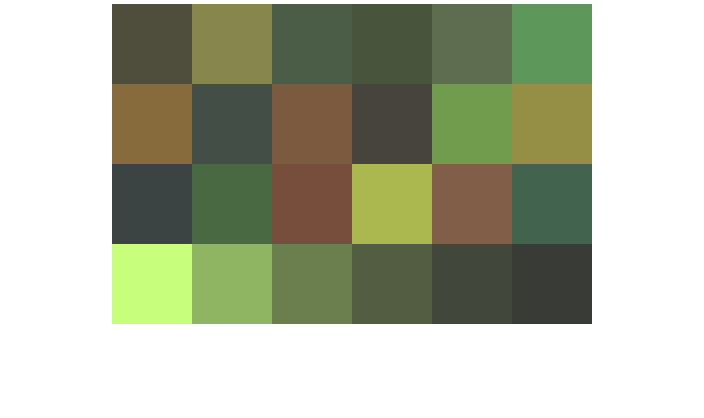

ieNewGraphWin;
imshow(pred_A_mat1)
title("4")

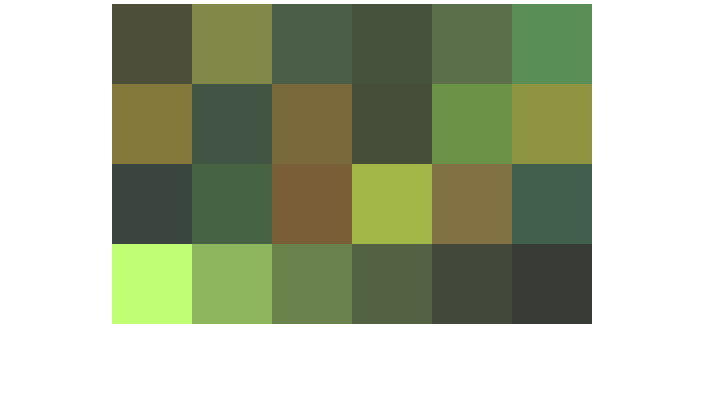


ieNewGraphWin;
imshow(pred_A_mat2)
title("A Prediciton 2 (w SVD)")

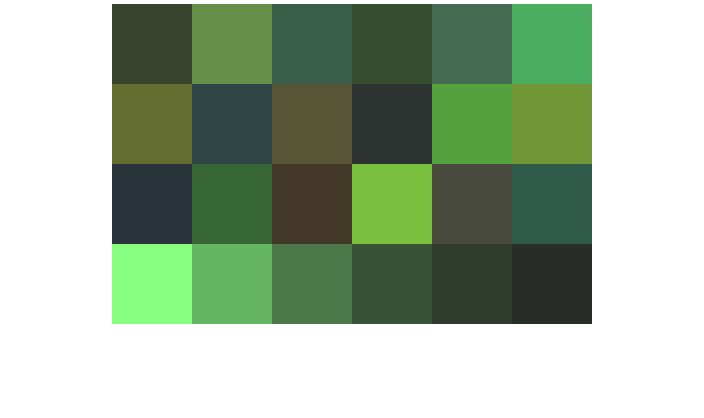


ieNewGraphWin;
imshow(pred_CWF_mat1)
title("CWF Prediciton 1 (w/o SVD)")

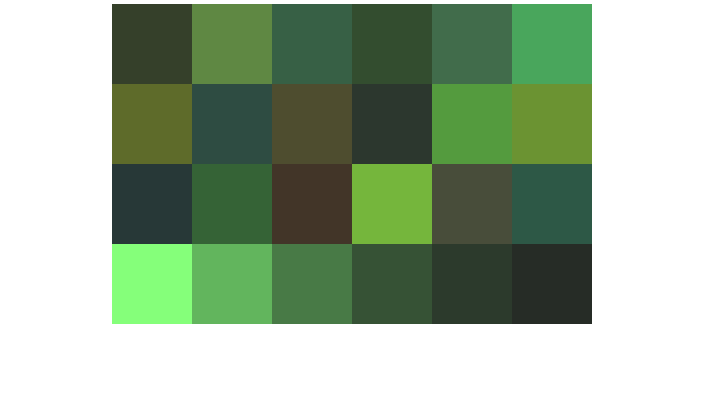


ieNewGraphWin;
imshow(pred_CWF_mat2)
title("CWF Prediciton 2 (w SVD)")

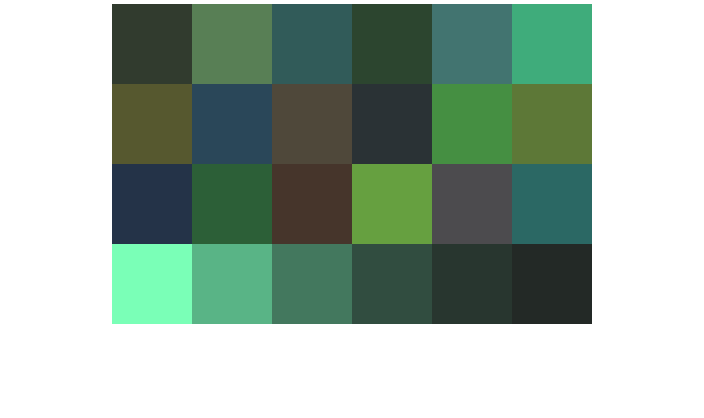


ieNewGraphWin;
imshow(pred_Day_mat1)
title("Day Prediciton 1 (w/o SVD)")

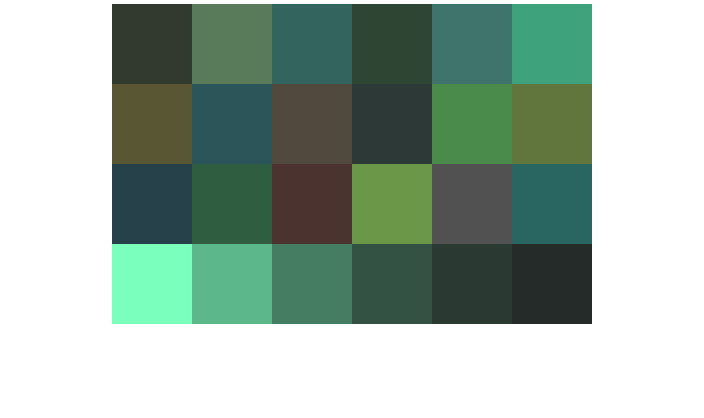


ieNewGraphWin;
imshow(pred_Day_mat2)
title("Day Prediciton 2 (w SVD)")

Here's a side-by-side comparison between predicted and measured data:

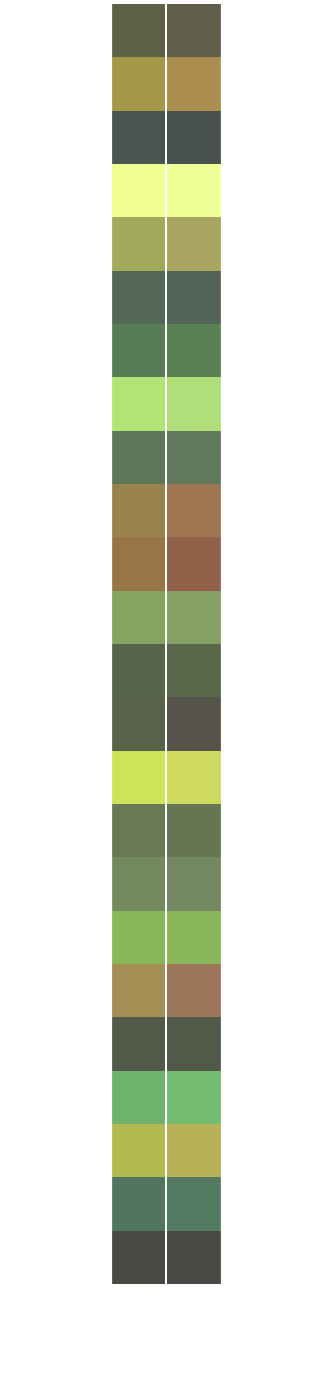

for ii=1:24
    pred_A_comp_rgb = pred_A_2b .* infoA.ExposureTime + infoA.BlackLevel(1);
    pred_A_comp_img = ones(80).*permute(pred_A_comp_rgb(ii,:)./255,[1 3 2]);
    meas_A_comp_rgb = rgb_mean_A .* infoA.ExposureTime + infoA.BlackLevel(1);
    meas_A_comp_img = ones(80).*permute(meas_A_comp_rgb(ii,:)./255,[1 3 2]);
    comp_img((ii-1)*80+1:(ii)*80,:,:) = [pred_A_comp_img,ones(80,3,3),meas_A_comp_img];
end
imshow(comp_img)

function to calculate CIELAB deltaE given two RGB matrices

function cielab_diff = calculate_cielab_diff(rgb1, rgb2)
    rgb1_normalized = rgb1 ./ max(max(rgb1));
    rgb2_normalized = rgb2 ./ max(max(rgb2));
    % cielab1 = rgb2lab(rgb1_normalized);
    % cielab2 = rgb2lab(rgb2_normalized);
    cielab1 = xyz2lab(rgb2xyz(rgb1_normalized));
    cielab2 = xyz2lab(rgb2xyz(rgb2_normalized));
    m = size(cielab1,1);
    cielab_diff = zeros(m,1);
    for i = 1:m
        cielab_diff(i) = norm(cielab1(i,:)-cielab2(i,:));
    end
end